# Winner-take-all

clear;
clc;
addpath('../funcs');
load ../../data/all4000_withAttn_0_0.5_0_0.05_Iattn_0.02.mat;
filepath = '../../paper/figure4/';
condition = {'Original', 'Condition: S1', 'Condition: S2','Condition: S1S2','Condition: S1S2+A1','Condition: S1S2+A2'};

solidAlpha = 1*256;
dashAlpha = 1*256;
solidColors = [[127 88 175 solidAlpha]; [100 197 235 solidAlpha]; [232 77 138 solidAlpha]; [254 179 38 solidAlpha]]/256;
dashColors = [[127 88 175 dashAlpha]; [100 197 235 dashAlpha]; [232 77 138 dashAlpha]; [254 179 38 dashAlpha]]/256;

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5
Delta_e_steps = 200;

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
Delta_i_steps = 200;

Iattn = 0.02;
time = 9000;
stimIn = 5000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

## Time-course: circle only attn

Delta_E = 0.12;
Delta_I = 0.04;

[r,~,~] = onlyAttn(Delta_E, Delta_I, Iattn, time);
r = r*1000;

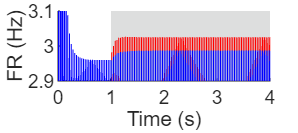

pop = 1;
figure();

hold on;
 
recX = [1 4 4 1];
recY = [0 0 5 5];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);
% hold on;
plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);


hold off;
axis([0 4 2.9 3.1]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_circle_only');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

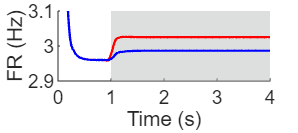

figure();

hold on;

recX = [1 4 4 1];
recY = [0 0 5 5];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond4,'r','LineWidth',1);
plot(timeax,cond5,'b','LineWidth',1);

hold off;
axis([0 4 2.9 3.1]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_circle_only_env');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

## Time-course: circle sens+attn

Delta_E = 0.12;
Delta_I = 0.04;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time, stimIn);
r = r*1000;

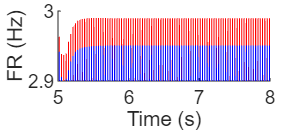

pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 5 5];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 2.9 3]);
xlabel("Time (s)");
ylabel("FR (Hz)");
yticks([2.9 3]);
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_L23E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

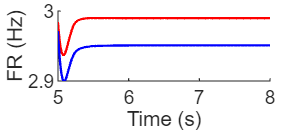

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 5 5];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond4,'r','LineWidth',1);
plot(timeax,cond5,'b','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 2.9 3]);
xlabel("Time (s)");
ylabel("FR (Hz)");
yticks([2.9 3]);
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_L23E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

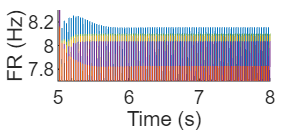

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 7.7 8.3]);
xlabel("Time (s)");
ylabel("FR (Hz)");
% yticks([2.9 3]);
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_L5E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

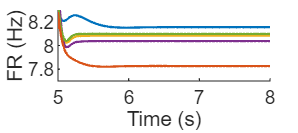

figure();

hold on;

recX = [1 4 4 1];
recY = [0 0 200 200];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 7.7 8.3]);
xlabel("Time (s)");
ylabel("FR (Hz)");
% yticks([2.9 3]);
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_L5E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Line chart: circle

% figure();
% [~,~,~,~,~,level,~] = record(r/1000, time);
% level_norm = normBetween01(level,2);
% condax = [0 1 2 3 4 5];
% for layer = 1:4
%     pop_E = (layer-1)*2 + 1;
%     pop_I = layer*2;
% 
%     plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
%     hold on;
%     plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
% 
% end
% 
% ylabel("Normalized firing rate");
% % xlabel("Conditions");
% xlim([0 5]);
% xticks([0 1 2 3 4 5]);
% xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
% ylim([0 1]);
% yticks([0 1]);
% yticklabels(["Min" "Max"]);
% 
% x0 = 0; y0 = 0; width = 4.5; height = 4.5;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
% set(gca, 'FontName', 'Arial');
% set(gca,'FontSize',8);
% 
% filename = append(filepath,'tc_circle_lChart');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

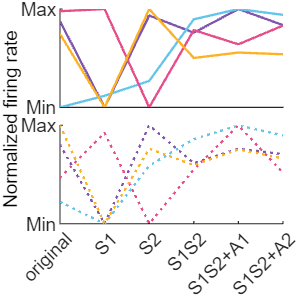

filepath = '../../paper/figure5/';
figure();
[~,~,~,~,~,level,~] = record(r/1000, time);
level_norm = normBetween01(level,2);
condax = [0 1 2 3 4 5];

% Create a subplot for the upper half
subplot(2, 1, 1); 
hold on;
for layer = 1:4
    pop_E = (layer-1)*2 + 1;
    plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
end
xlim([0 5]);
xticks([]); % No xticks for the upper plot
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.2 0.64 0.75 0.33]); % Adjust the position manually

% Create a subplot for the lower half
subplot(2, 1, 2); 
hold on;
for layer = 1:4
    pop_I = layer*2;
    plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
end
xlabel("Conditions");
xlim([0 5]);
xticks([0 1 2 3 4 5]);
xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.2 0.25 0.75 0.33]); % Adjust the position manually

% Add y label to the figure using annotation
annotation('textbox', [0.17, 0.2, 0.8, 0.2], 'String', 'Normalized firing rate',...
    'HorizontalAlignment', 'center', 'Rotation', 90, 'FontSize', 8, 'FontName', 'Arial',...
    'EdgeColor', 'none');

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'tc_circle_lChart');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Time-course: plus

Delta_E = 0.08;
Delta_I = 0.02;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time, stimIn);
r = r*1000;

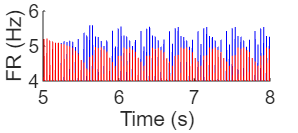

filepath = '../../paper/figure4/';
pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

% plot(timeax(1:100000),squeeze(r(pop,1:100000,4)),'r','LineWidth',0.5);
% plot(timeax(1:100000),squeeze(r(pop,1:100000,5)),'b','LineWidth',0.5);
% plot(timeax(100001:400000),squeeze(r(pop,100001:400000,5)),'b','LineWidth',0.5);
% plot(timeax(100001:400000),squeeze(r(pop,100001:400000,4)),'r','LineWidth',0.5);
plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 4 6]);
xlabel("Time (s)");
ylabel("FR (Hz)");
% yticks([2.9 3]);
xticks([5 6 7 8]);


x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L23E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

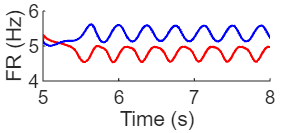

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond4,'r','LineWidth',1);
plot(timeax,cond5,'b','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 4 6]);
xlabel("Time (s)");
ylabel("FR (Hz)");
% yticks([2.9 3]);
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L23E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

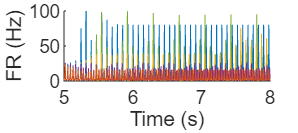

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 0 100]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L5E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

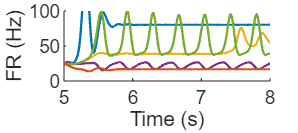

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 0 100]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L5E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Line chart: plus

% figure();
% [~,~,~,~,~,level,~] = record(r/1000, time);
% level_norm = normBetween01(level,2);
% condax = [0 1 2 3 4 5];
% for layer = 1:4
%     pop_E = (layer-1)*2 + 1;
%     pop_I = layer*2;
% 
%     plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
%     hold on;
%     plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
% 
% end
% 
% ylabel("Normalized firing rate");
% % xlabel("Conditions");
% xlim([0 5]);
% xticks([0 1 2 3 4 5]);
% xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
% ylim([-0.1 1.1]);
% yticks([0 1]);
% yticklabels(["Min" "Max"]);
% 
% x0 = 0; y0 = 0; width = 4.5; height = 4.5;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
% set(gca, 'FontName', 'Arial');
% set(gca,'FontSize',8);
% 
% filename = append(filepath,'tc_plus_lChart');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

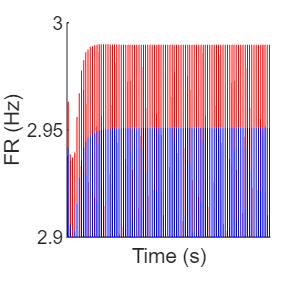

filepath = '../../paper/figure5/';
figure();
[~,~,~,~,~,level,~] = record(r/1000, time);
level_norm = normBetween01(level,2);
condax = [0 1 2 3 4 5];

% Create a subplot for the upper half
subplot(2, 1, 1); 
hold on;
for layer = 1:4
    pop_E = (layer-1)*2 + 1;
    plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
end
xlim([0 5]);
xticks([]); % No xticks for the upper plot
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.2 0.64 0.75 0.33]); % Adjust the position manually

% Create a subplot for the lower half
subplot(2, 1, 2); 
hold on;
for layer = 1:4
    pop_I = layer*2;
    plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
end
xlabel("Conditions");
xlim([0 5]);
xticks([0 1 2 3 4 5]);
xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.2 0.25 0.75 0.33]); % Adjust the position manually

% Add y label to the figure using annotation
annotation('textbox', [0.17, 0.2, 0.8, 0.2], 'String', 'Normalized firing rate',...
    'HorizontalAlignment', 'center', 'Rotation', 90, 'FontSize', 8, 'FontName', 'Arial',...
    'EdgeColor', 'none');

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'tc_plus_lChart');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Time-course: square

Delta_E = 0.3;
Delta_I = 0.02;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time, stimIn);
r = r*1000;

filepath = '../../paper/figure4/';
pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 28 30]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L23E');
print(filename, '-dpng', '-r600');

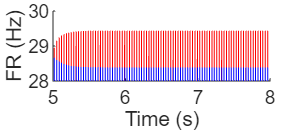

print(filename, '-dsvg', '-r600');

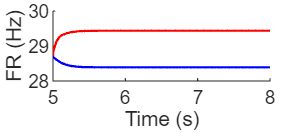

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond4,'r','LineWidth',1);
plot(timeax,cond5,'b','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 28 30]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L23E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

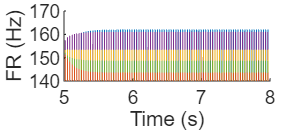

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 140 170]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L5E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

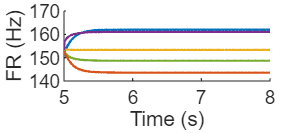

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 140 170]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L5E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Line chart: square

% figure();
% [~,~,~,~,~,level,~] = record(r/1000, time);
% level_norm = normBetween01(level,2);
% condax = [0 1 2 3 4 5];
% for layer = 1:4
%     pop_E = (layer-1)*2 + 1;
%     pop_I = layer*2;
% 
%     plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
%     hold on;
%     plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
% 
% end
% 
% ylabel("Normalized firing rate");
% % xlabel("Conditions");
% xlim([0 5]);
% xticks([0 1 2 3 4 5]);
% xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
% ylim([-0.1 1.1]);
% yticks([0 1]);
% yticklabels(["Min" "Max"]);
% 
% x0 = 0; y0 = 0; width = 4.5; height = 4.5;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
% set(gca, 'FontName', 'Arial');
% set(gca,'FontSize',8);
% 
% filename = append(filepath,'tc_sq_lChart');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

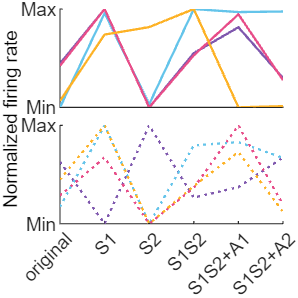

filepath = '../../paper/figure5/';
figure();
[~,~,~,~,~,level,~] = record(r/1000, time);
level_norm = normBetween01(level,2);
condax = [0 1 2 3 4 5];

% Create a subplot for the upper half
subplot(2, 1, 1); 
hold on;
for layer = 1:4
    pop_E = (layer-1)*2 + 1;
    plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
end
xlim([0 5]);
xticks([]); % No xticks for the upper plot
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.2 0.64 0.75 0.33]); % Adjust the position manually

% Create a subplot for the lower half
subplot(2, 1, 2); 
hold on;
for layer = 1:4
    pop_I = layer*2;
    plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
end
xlabel("Conditions");
xlim([0 5]);
xticks([0 1 2 3 4 5]);
xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.2 0.25 0.75 0.33]); % Adjust the position manually

% Add y label to the figure using annotation
annotation('textbox', [0.17, 0.2, 0.8, 0.2], 'String', 'Normalized firing rate',...
    'HorizontalAlignment', 'center', 'Rotation', 90, 'FontSize', 8, 'FontName', 'Arial',...
    'EdgeColor', 'none');

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'tc_sq_lChart');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Time-course: Triangle

Delta_E = 0.46;
Delta_I = 0.045;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time, stimIn);
r = r*1000;

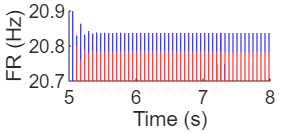

filepath = '../../paper/figure4/';
pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

% plot(timeax(1:100000),squeeze(r(pop,1:100000,4)),'r','LineWidth',0.3);
% plot(timeax(1:100000),squeeze(r(pop,1:100000,5)),'b','LineWidth',0.3);
% plot(timeax(100001:400000),squeeze(r(pop,100001:400000,5)),'b','LineWidth',0.3);
% plot(timeax(100001:400000),squeeze(r(pop,100001:400000,4)),'r','LineWidth',0.3);

plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 20.7 20.9]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L23E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

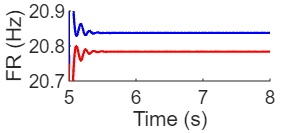

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond4,'r','LineWidth',1);
plot(timeax,cond5,'b','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 20.7 20.9]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L23E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

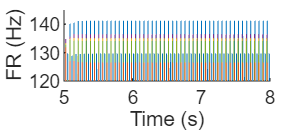

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 120 145]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L5E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

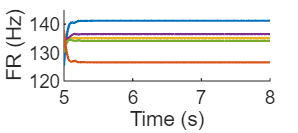

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 120 145]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L5E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Line chart: triangle

% figure();
% [~,~,~,~,~,level,~] = record(r/1000, time);
% level_norm = normBetween01(level,2);
% condax = [0 1 2 3 4 5];
% for layer = 1:4
%     pop_E = (layer-1)*2 + 1;
%     pop_I = layer*2;
% 
%     plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
%     hold on;
%     plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
% 
% end
% 
% ylabel("Normalized firing rate");
% % xlabel("Conditions");
% xlim([0 5]);xticks([0 1 2 3 4 5]);
% xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
% ylim([-0.1 1.1]);
% yticks([0 1]);
% yticklabels(["Min" "Max"]);
% 
% x0 = 0; y0 = 0; width = 4.5; height = 4.5;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
% set(gca, 'FontName', 'Arial');
% set(gca,'FontSize',8);
% 
% filename = append(filepath,'tc_tri_lChart');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

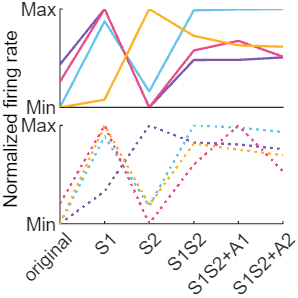

filepath = '../../paper/figure5/';
figure();
[~,~,~,~,~,level,~] = record(r/1000, time);
level_norm = normBetween01(level,2);
condax = [0 1 2 3 4 5];

% Create a subplot for the upper half
subplot(2, 1, 1); 
hold on;
for layer = 1:4
    pop_E = (layer-1)*2 + 1;
    plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
end
xlim([0 5]);
xticks([]); % No xticks for the upper plot
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.2 0.64 0.75 0.33]); % Adjust the position manually

% Create a subplot for the lower half
subplot(2, 1, 2); 
hold on;
for layer = 1:4
    pop_I = layer*2;
    plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
end
xlabel("Conditions");
xlim([0 5]);
xticks([0 1 2 3 4 5]);
xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.2 0.25 0.75 0.33]); % Adjust the position manually

% Add y label to the figure using annotation
annotation('textbox', [0.17, 0.2, 0.8, 0.2], 'String', 'Normalized firing rate',...
    'HorizontalAlignment', 'center', 'Rotation', 90, 'FontSize', 8, 'FontName', 'Arial',...
    'EdgeColor', 'none');

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'tc_tri_lChart');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Scatter plots: Green

load ../../data/all4000_onlyAttn_0_0.5_0_0.05_Iattn_0.02.mat;
envSheet = envSheet*1000;

pops = ["1L2/3E","1L2/3I","1L4E","1L4I","1L5E","1L5I","1L6E","1L6I"];
conds = ["original", "S1", "S2", "S1S2", "S1S2+A1", "S1S2+A2"];
filepath = '../../paper/figure3/';

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 200;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 1;
markSZ = 50;
steps = size(envSheet,1);

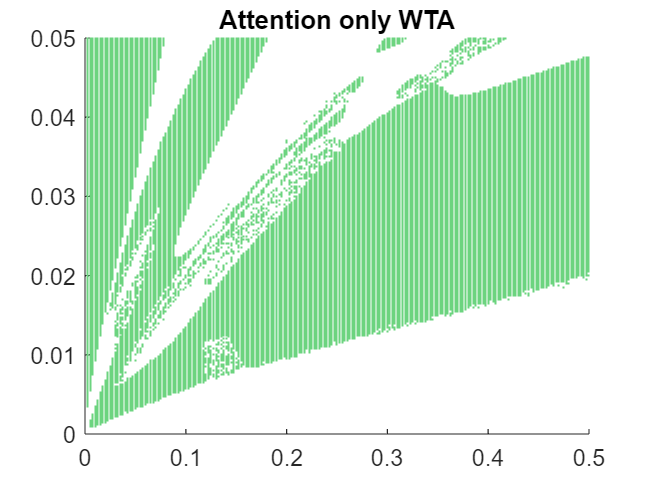

pop = 1;
WTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = envSheet(i,j,pop,1); cond1 = envSheet(i,j,pop,2); cond2 = envSheet(i,j,pop,3);
        cond3 = envSheet(i,j,pop,4); cond4 = envSheet(i,j,pop,5); cond5 = envSheet(i,j,pop,6);
        if cond4>cond5
            WTA(i,j) = 1;

        end
    end
end

WTA = WTA == 1;

figure();
for i = 1:steps
    x = Delta_e(WTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Attention only WTA");

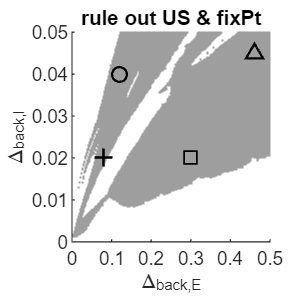

% load ../../data/all4000_withAttn_0_0.5_0_0.05_Iattn_0.02.mat;
ruleOut = zeros(steps,steps);
maxPks = 5;

for i = 1:steps
    for j = 1:steps
        cond4 = squeeze(psdPeaksSheet(i,j,:,5)); cond5 = squeeze(psdPeaksSheet(i,j,:,6));
        tmp = max([cond4; cond5]);
        if tmp<=maxPks && tmp>=1 
            ruleOut(i,j) = 1;
        end
    end
end

ruleOut = ruleOut == 1;

figure();
for i = 1:steps
    x = Delta_e(ruleOut(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#9E9E9E"); % green
    hold on;
end
scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.08, 0.02, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.3, 0.02, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.46, 0.045, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);
title("rule out US & fixPt");

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

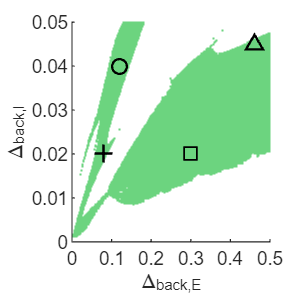

pop = 1;
WTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = envSheet(i,j,pop,1); cond1 = envSheet(i,j,pop,2); cond2 = envSheet(i,j,pop,3);
        cond3 = envSheet(i,j,pop,4); cond4 = envSheet(i,j,pop,5); cond5 = envSheet(i,j,pop,6);
        if cond4>cond5
            WTA(i,j) = 1;
        end
    end
end

WTA = WTA == 1;
WTA = and(WTA,ruleOut);

figure();
for i = 1:steps
    x = Delta_e(WTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end

scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.08, 0.02, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.3, 0.02, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.46, 0.045, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'scatter_green');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Scatter plots: Blue

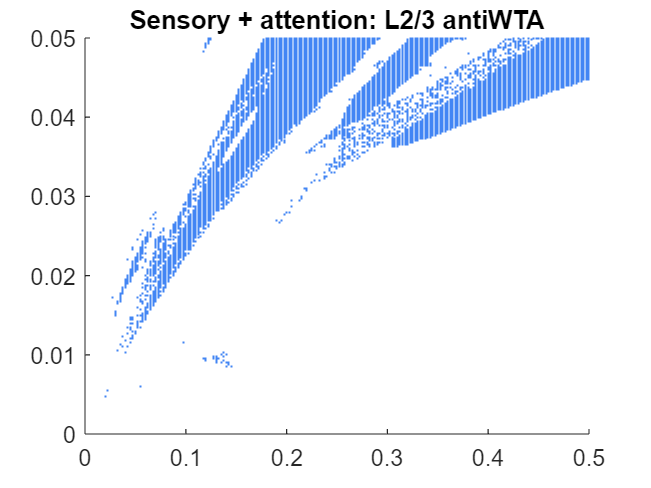

load ../../data/all4000_withAttn_0_0.5_0_0.05_Iattn_0.02.mat;
pop = 1;
antiWTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = envSheet(i,j,pop,1); cond1 = envSheet(i,j,pop,2); cond2 = envSheet(i,j,pop,3);
        cond3 = envSheet(i,j,pop,4); cond4 = envSheet(i,j,pop,5); cond5 = envSheet(i,j,pop,6);
        if cond4<cond5
            antiWTA(i,j) = 1;
        end
    end
end

antiWTA = antiWTA == 1;
antiWTA = and(antiWTA,ruleOut);

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#4285F4"); % blue
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Sensory + attention: L2/3 antiWTA");

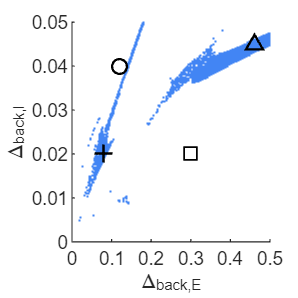

antiWTA = and(WTA,antiWTA);

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#4285F4"); % blue
    hold on;
end

scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.08, 0.02, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.3, 0.02, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.46, 0.045, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'scatter_blue');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Scatter plots: Yellow

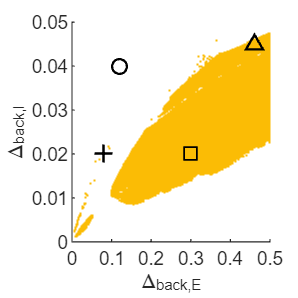

load ../../data/all4000_withAttn_0_0.5_0_0.05_Iattn_0.02.mat
pop = 5;
order = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = envSheet(i,j,pop,1); cond1 = envSheet(i,j,pop,2); cond2 = envSheet(i,j,pop,3);
        cond3 = envSheet(i,j,pop,4); cond4 = envSheet(i,j,pop,5); cond5 = envSheet(i,j,pop,6);
        if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5
            order(i,j) = 1;
        end
    end
end

order = order == 1;
order = and(order,WTA);

figure();
for i = 1:steps
    x = Delta_e(order(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FBBC05"); % yellow
    hold on;
end

scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.08, 0.02, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.3, 0.02, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.46, 0.045, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'scatter_yellow');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Scatter plots: Red

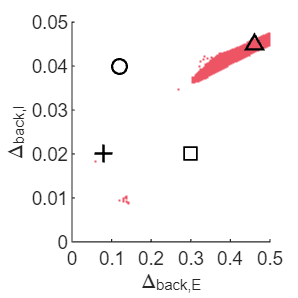

order = and(order,antiWTA);

figure();
for i = 1:steps
    x = Delta_e(order(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#ED5564"); % red
    hold on;
end

scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.08, 0.02, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.3, 0.02, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.46, 0.045, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'scatter_red');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## get four markers

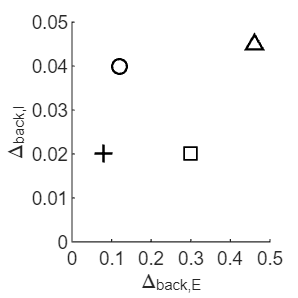

figure();
hold on;

scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.08, 0.02, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.3, 0.02, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.46, 0.045, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'four_markers');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');